# 实验4

 
clc
clear

z = -1;
p = [0,1];
sys1 = zpk(z,p,1);
num = 1;
den = [1,4,20];
sys2 = tf(num,den);
sys = sys1*sys2;
%绘制根轨迹图
[r,k] = rlocus(sys)

r = 	1.0e+02 *

   0.0000 + 0.0000i   0.0008 + 0.0000i   0.0009 + 0.0000i   0.0011 + 0.0000i   0.0014 + 0.0000i   0.0017 + 0.0000i   0.0021 + 0.0000i   0.0028 + 0.0000i   0.0043 + 0.0000i   0.0044 + 0.0000i   0.0044 + 0.0002i   0.0044 + 0.0010i   0.0043 + 0.0023i   0.0042 + 0.0033i   0.0040 + 0.0041i   0.0038 + 0.0049i   0.0036 + 0.0057i   0.0034 + 0.0066i   0.0031 + 0.0074i   0.0027 + 0.0084i   0.0023 + 0.0094i   0.0018 + 0.0105i   0.0011 + 0.0117i   0.0002 + 0.0130i  -0.0010 + 0.0146i  -0.0027 + 0.0165i  -0.0040 + 0.0177i  -0.0059 + 0.0189i  -0.0063 + 0.0190i  -0.0068 + 0.0192i  -0.0078 + 0.0194i  -0.0078 + 0.0194i  -0.0079 + 0.0194i  -0.0089 + 0.0193i  -0.0098 + 0.0191i  -0.0113 + 0.0185i  -0.0132 + 0.0173i  -0.0147 + 0.0162i  -0.0172 + 0.0138i  -0.0194 + 0.0110i  -0.0214 + 0.0073i  -0.0221 + 0.0051i  -0.0225 + 0.0036i  -0.0229 + 0.0007i  -0.0229 + 0.0000i  -0.0222 + 0.0000i  -0.0193 + 0.0000i  -0.0158 + 0.0000i  -0.0143 + 0.0000i  -0.0133 + 0.0000i
   0.0100 + 0.0000i   0.0088 + 0.

k = 	1.0e+07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


hold on
t = -5:0.01:10

t =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


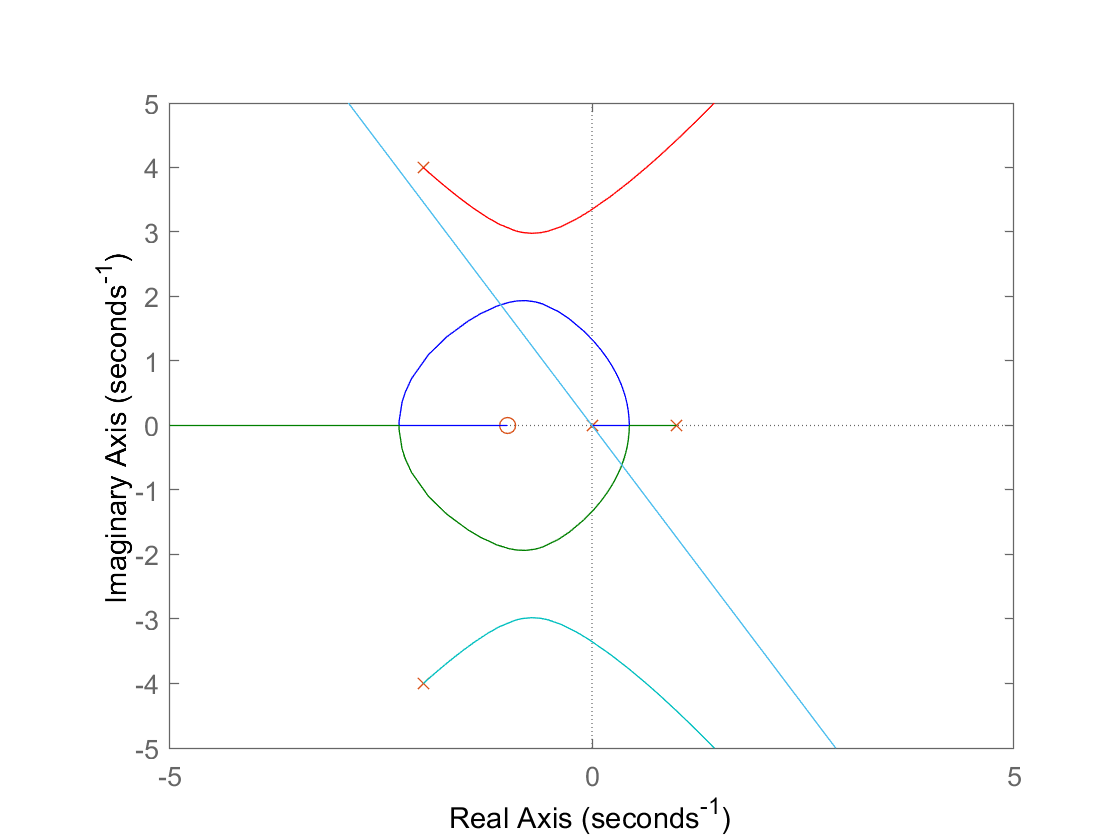

y = (-1)*t*sqrt(3);
plot(t,y)

%寻找相交点
for i = 1:70
    if abs(sqrt(3)*real(r(2,i))) == abs(imag(r(2,i)))+0.5
        disp(i)
    end
end